clear all;
close all;

m1 = 2500; %kg
m2 = 320; %kg
k1 = 80000; %N/m
k2 = 500000; %N/m
b1 = 350; % Ns/m
b2 = 15020; %Ns/m

s = tf('s');
G1 = ((m1+m2)*s^2+b2*s+k2)/((m1*s^2+b1*s+k1)*(m2*s^2+(b1+b2)*s+(k1+k2))-(b1*s+k1)*(b1*s+k1))

G1 =
 
                  2820 s^2 + 15020 s + 500000
  ------------------------------------------------------------
  800000 s^4 + 3.854e07 s^3 + 1.481e09 s^2 + 1.377e09 s + 4e10
 
Continuous-time transfer function.



G2 = (-m1*b2*s^3-m1*k2*s^2)/((m1*s^2+b1*s+k1)*(m2*s^2+(b1+b2)*s+(k1+k2))-(b1*s+k1)*(b1*s+k1))

G2 =
 
                  -3.755e07 s^3 - 1.25e09 s^2
  ------------------------------------------------------------
  800000 s^4 + 3.854e07 s^3 + 1.481e09 s^2 + 1.377e09 s + 4e10
 
Continuous-time transfer function.



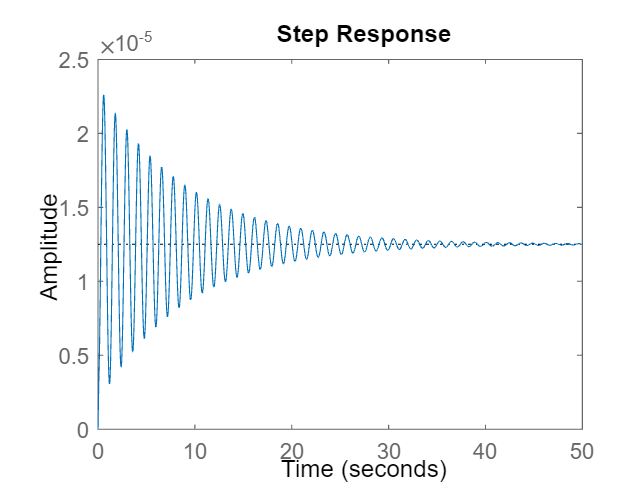


step(G1)

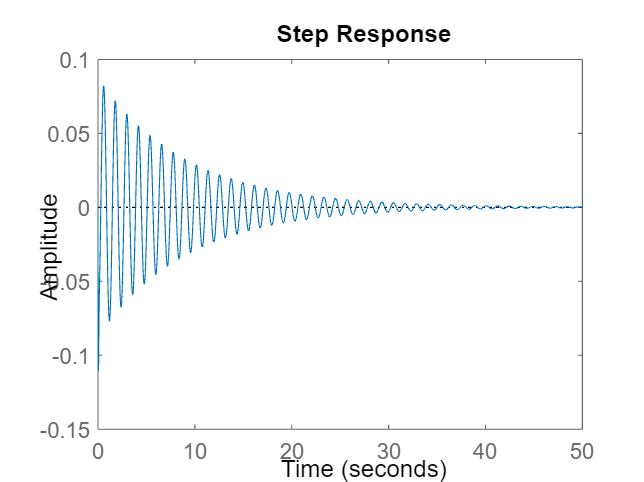

step(0.1*G2)


%PID

F = minreal(G2/G1)

F =
 
  -1.332e04 s^3 - 4.433e05 s^2
  ----------------------------
     s^2 + 5.326 s + 177.3
 
Continuous-time transfer function.



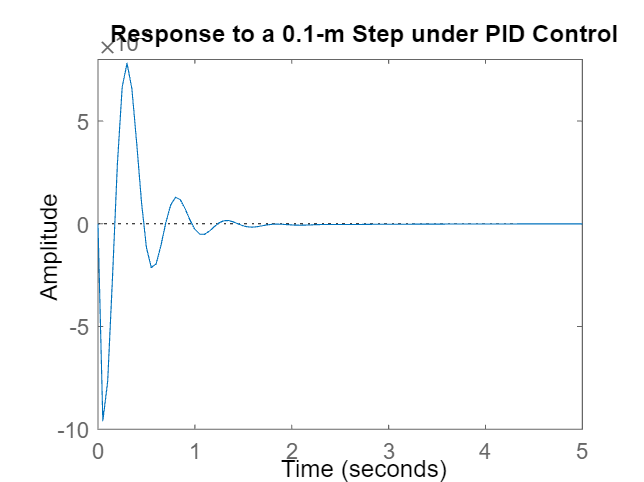


Kd = 208025;
Kp = 832100;
Ki = 624075;
Cpid = pid(Kp,Ki,Kd);
sys_cl=F*feedback(G1,Cpid);

t=0:0.05:5;
step(0.1*sys_cl,t)
title('Response to a 0.1-m Step under PID Control')


z1 = 1;
z2 = 3;
p1 = 0;%34
C = (s+z1)*(s+z2)/(s+p1);
[R,K] = rlocus(C*G1)

R = 1.0e+04 *

   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i
  -0.0024 + 0.0035i  -0.0028 + 0.0

K = 1.0e+07 *

         0    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0006    0.0007    0.0007    0.0008    0.0009    0.0010    0.0012    0.0012    0.0012    0.0012    0.0013    0.0015    0.0016    0.0018    0.0020    0.0023    0.0025    0.0028    0.0032    0.0035    0.0040    0.0044    0.0049    0.0055    0.0062    0.0069    0.0077    0.0086    0.0096    0.0108    0.0120    0.0135    0.0150    0.0168    0.0188    0.0210    0.0235    0.0262    0.0293    0.0328


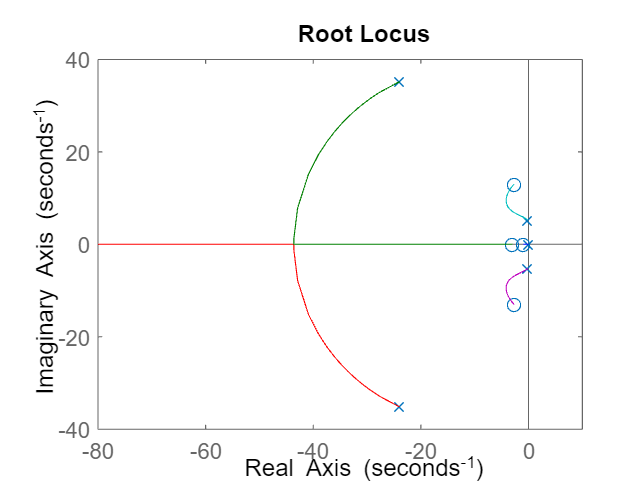

rlocus(G1*C)

Kd = K(34)

Kd = 5.5248e+04

Kp = Kd*(z1+z2)

Kp = 2.2099e+05

Ki = Kd*z1*z2

Ki = 1.6574e+05

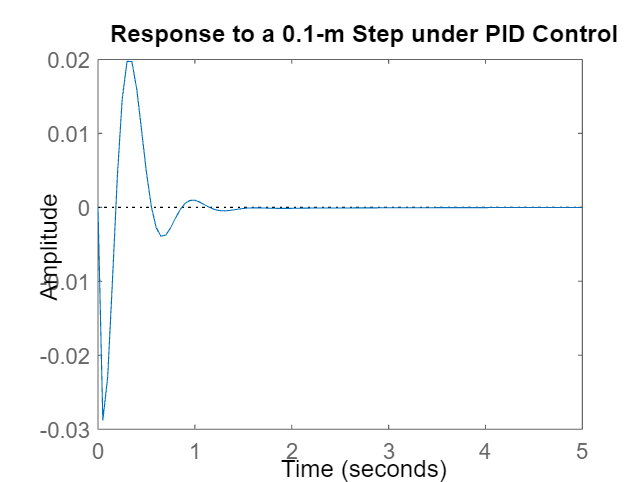

Cpid = pid(Kp,Ki,Kd);
sys_cl=F*feedback(G1,Cpid);

t=0:0.05:5;
step(0.1*sys_cl,t)
title('Response to a 0.1-m Step under PID Control')


Kd = 8*Kd

Kd = 4.4199e+05

Kp = 8*Kp

Kp = 1.7679e+06

Ki = 8*Ki

Ki = 1.3260e+06

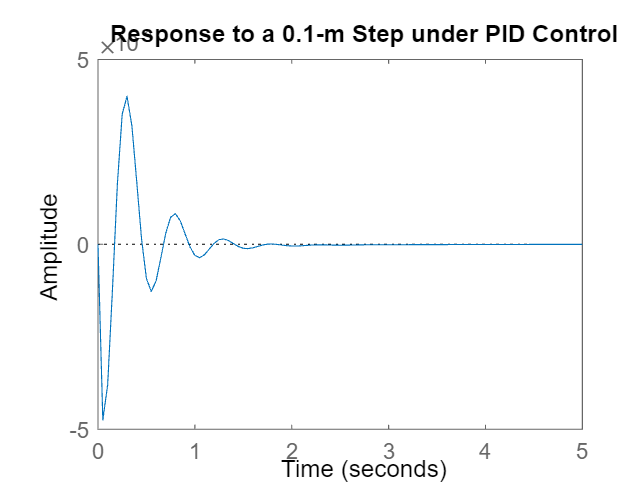

Cpid = pid(Kp,Ki,Kd);
sys_cl=F*feedback(G1,Cpid);

t=0:0.05:5;
step(0.1*sys_cl,t)
title('Response to a 0.1-m Step under PID Control')


%Root locus
rlocus(G1)
z=-log(0.05)/sqrt(pi^2+(log(0.05)^2))

z = 0.6901

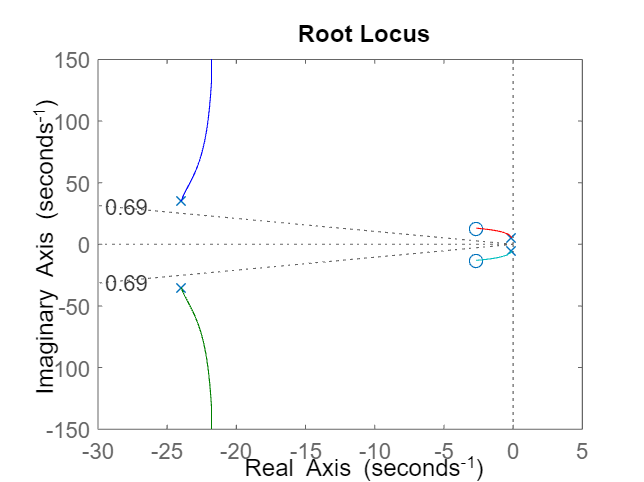

sgrid(z,0)


[num,den] = tfdata(G1)

num = 1×1 cell array
    {[0 0 2820 15020 500000]}


den = 1×1 cell array
    {[800000 38537000 1.4809e+09 1.3766e+09 4.0000e+10]}


[A,B,C,D] = tf2ss(num{1},den{1})

A = 1.0e+04 *

   -0.0048   -0.1851   -0.1721   -5.0000
    0.0001         0         0         0
         0    0.0001         0         0
         0         0    0.0001         0


B =      1
     0
     0
     0


C =          0    0.0035    0.0188    0.6250


D = 0


z1=3+3.5i;
z2=3-3.5i;
p1=30;
p2=60;
numc=conv([1 z1],[1 z2]);
denc=conv([1 p1],[1 p2]);
C=tf(numc,denc);

rlocus(C*G1)
[R,K] = rlocus(C*G1)

R = 1.0e+03 *

  -0.0600 + 0.0000i  -0.0540 + 0.0000i  -0.0528 + 0.0000i  -0.0512 + 0.0000i  -0.0490 + 0.0000i  -0.0452 + 0.0000i  -0.0426 + 0.0000i  -0.0421 + 0.0000i  -0.0421 + 0.0005i  -0.0417 + 0.0054i  -0.0411 + 0.0086i  -0.0403 + 0.0114i  -0.0392 + 0.0142i  -0.0375 + 0.0170i  -0.0362 + 0.0186i  -0.0354 + 0.0193i  -0.0345 + 0.0199i  -0.0338 + 0.0202i  -0.0338 + 0.0202i  -0.0338 + 0.0202i  -0.0338 + 0.0202i  -0.0337 + 0.0202i  -0.0337 + 0.0202i  -0.0304 + 0.0204i  -0.0300 + 0.0204i  -0.0296 + 0.0203i  -0.0289 + 0.0202i  -0.0278 + 0.0199i  -0.0259 + 0.0195i  -0.0243 + 0.0190i  -0.0230 + 0.0187i  -0.0217 + 0.0184i  -0.0206 + 0.0181i  -0.0195 + 0.0178i  -0.0185 + 0.0175i  -0.0175 + 0.0172i  -0.0166 + 0.0169i  -0.0157 + 0.0167i  -0.0148 + 0.0164i  -0.0140 + 0.0162i  -0.0132 + 0.0159i  -0.0125 + 0.0156i  -0.0117 + 0.0154i  -0.0110 + 0.0152i  -0.0104 + 0.0149i  -0.0097 + 0.0147i  -0.0091 + 0.0145i  -0.0085 + 0.0143i  -0.0080 + 0.0141i  -0.0075 + 0.0139i
  -0.0240 + 0.0352i  -0.0254 + 0.0

K = 1.0e+10 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005


axis([-40 10 -30 30])
z=-log(0.05)/sqrt(pi^2+(log(0.05)^2))

z = 0.6901

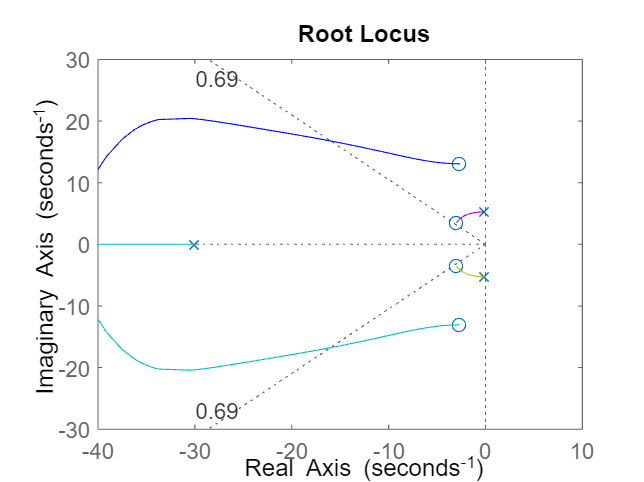

sgrid(z,0)


k = (K(65)+K(66))/2

k = 9.0299e+09

sys_cl=minreal(F*feedback(G1,k*C))

sys_cl =
 
                 -46.94 s^5 - 5787 s^4 - 2.251e05 s^3 - 2.812e06 s^2
  ----------------------------------------------------------------------------------
  s^6 + 138.2 s^5 + 3.184e07 s^4 + 3.608e08 s^3 + 7.341e09 s^2 + 3.747e10 s + 1.2e11
 
Continuous-time transfer function.



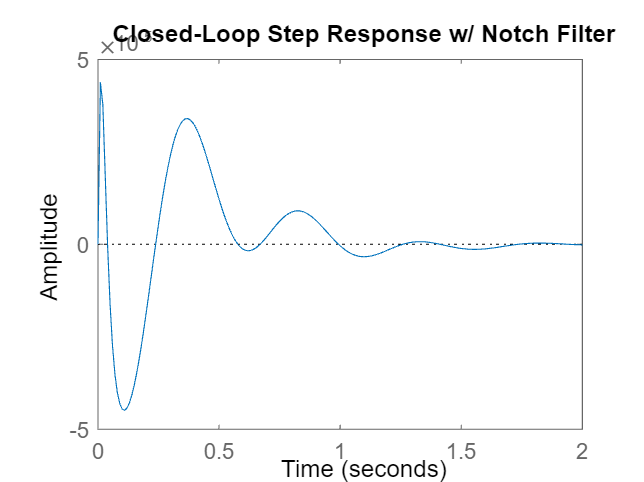


t=0:0.01:2;
step(0.1*sys_cl,t)
title('Closed-Loop Step Response w/ Notch Filter')

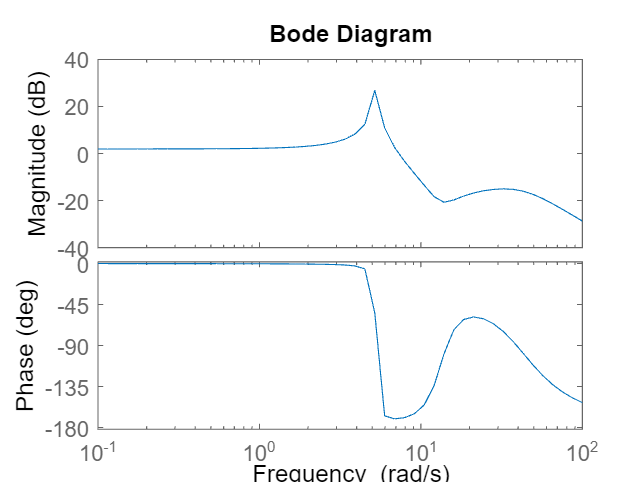


%Frekvencia
w = logspace(-1,2);
K=100000;
bode(K*G1,w)


a = (1-sin(70/180*pi))/(1+sin(70/180*pi));
w=5;
T=1/(w*sqrt(a));
aT=sqrt(a)/w;
C1 = tf([T 1],[aT 1])

C1 =
 
   1.134 s + 1
  -------------
  0.03527 s + 1
 
Continuous-time transfer function.



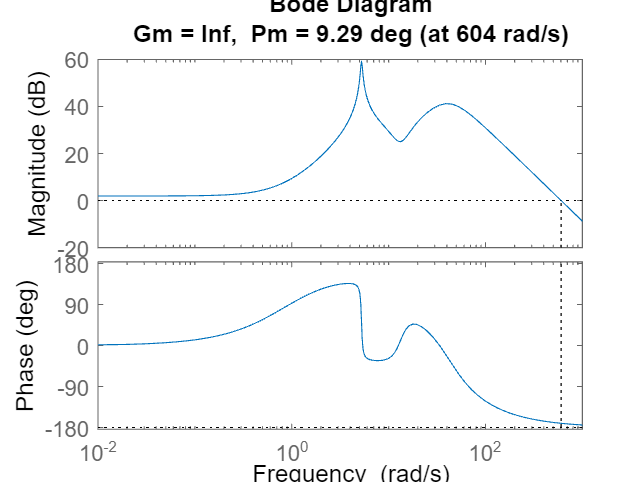

numc = conv([T 1], [T 1]);
denc = conv([aT 1], [aT 1]);
C = tf(numc,denc);
margin(K*C*G1)

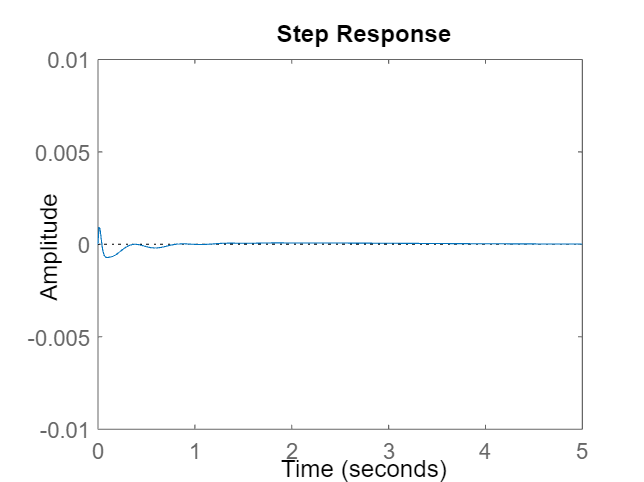


sys_cl = F*feedback(G1,400000*C);
t=0:0.01:5;
step(0.1*sys_cl,t)
axis([0 5 -.01 .01])